# Illustrating equal irradiance for uniform fields when f/# is equal

In class I described how lenses with the same f/# produce an equal irradiance image at the sensor.  This argument applies to images of uniform patches, and it is not true for dots or lines. I show the calculations using ISETCam here.

We go through that calculation in ISETCam and point out how this works for uniform areas and but needs a little more explanation for lines or points (not uniform areas).

ieInit

For uniform fields the picture and idea is shown in this comparison of two lenses with the same f/#.  The lens with the smaller aperture collects fewer rays from the top point of the arrow, compared to the lens with the larger aperture.  It will be the case that if we consider only a single point, the irradiance from that point alone will be larger for the lens with the larger diameter

However, the image from the larger diameter lens is magnified.  Thus if we consider many small regions they will be spread out over more of the image plane.  The magnification (spreading out of the image) counters the fact that a single point produces more irradiance.  The two factors cancel out, so that for a uniform patch the two lenses produce the same irradiance.  

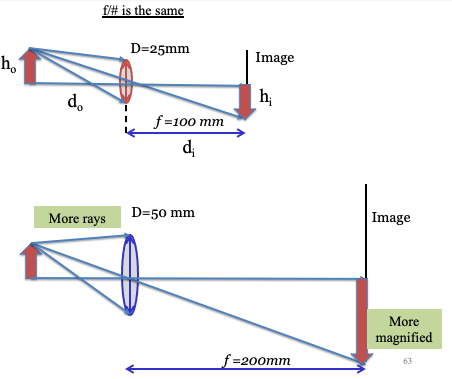

### Uniform scene

We illustrate this by creating a uniform scene and then calculating the optical image using two different focal lengths, but the same f/#.

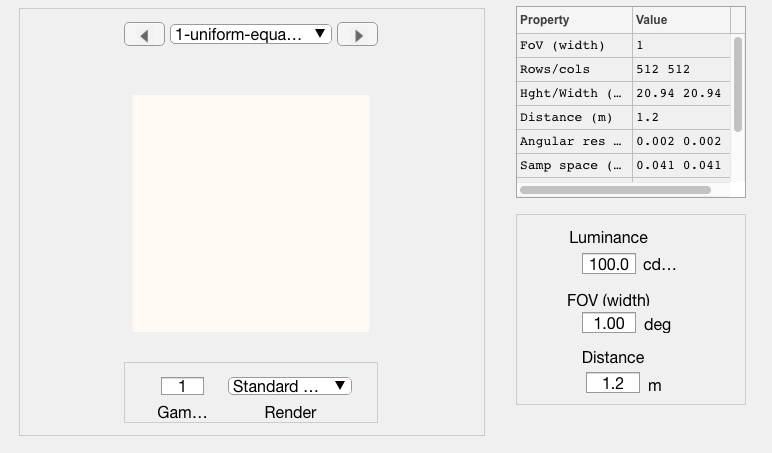

imSize = 512;
scene = sceneCreate('uniform ee',imSize);
scene = sceneSet(scene,'fov',1);
sceneWindow(scene);


% Here is the image.  Notice 
oi = oiCreate;
oi = oiCompute(oi,scene);
oiWindow(oi);
oiGet(oi,'mean illuminance')

ans = single
3.0734

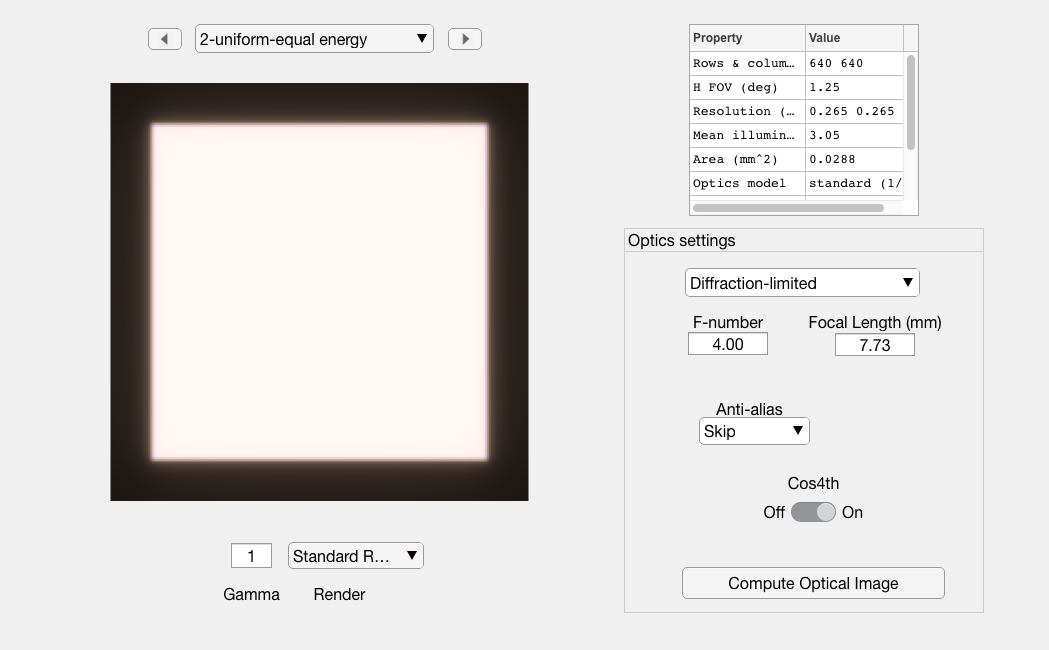


% Create an oi with a longer focal length, leaving the f/# the same.
oi2 = oiSet(oi,'optics focal length',oiGet(oi,'optics focal length')*2);
oi2 = oiCompute(oi2,scene);
oiWindow(oi2);

oiGet(oi2,'mean illuminance')

ans = single
3.0538

The small difference is probably something to do with the edge.

### Single line

Now, compare what happens when we create an image of a single line.  In that case, the two f/# lenses spread the light from the line over the same space - the linespread of two lenses is the same when the f/# is the same.

Compare the two plots, and you will see that the larger diameter lens has a higher illuminance.  The spread of the line is the same for the two lenses.

Here is a thin line

scene = sceneCreate('line',512);
scene = sceneSet(scene,'fov',1);

The image with the default oi

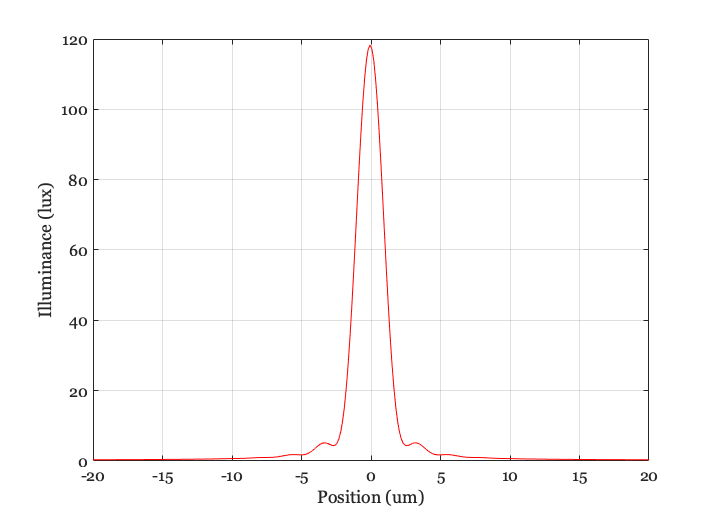

oi = oiCreate;
oi = oiCompute(oi,scene);
oiWindow(oi);

data1 = oiPlot(oi,'illuminance hline',[1 256]);
set(gca,'xlim',[-20 20],'xtick',[-20:5:20])

The image when we increase the focal length, but leave the f/# fixed.

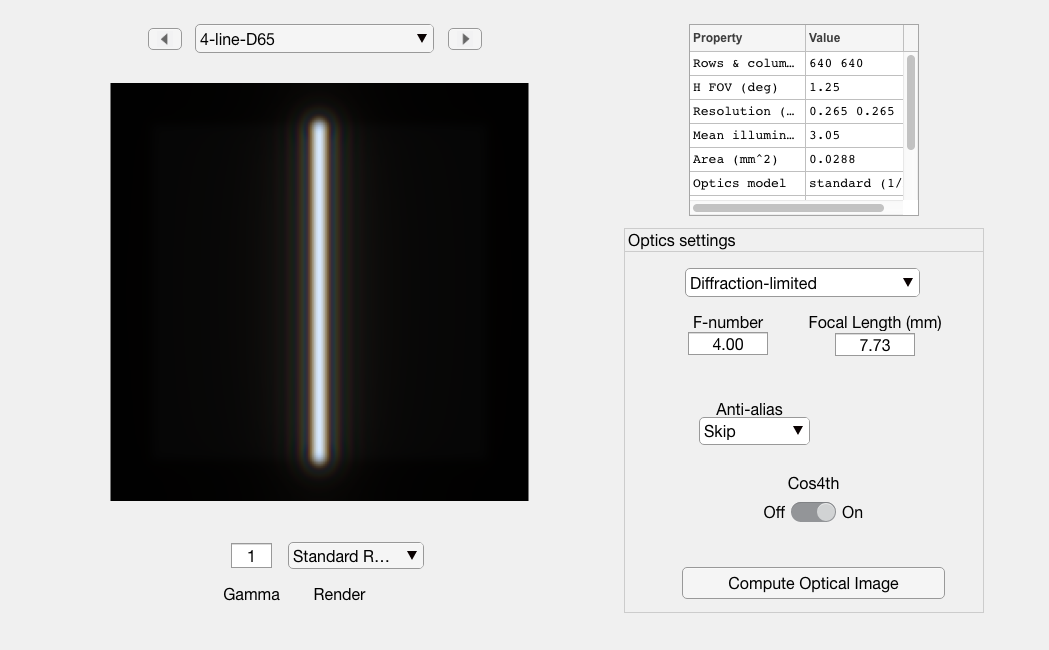

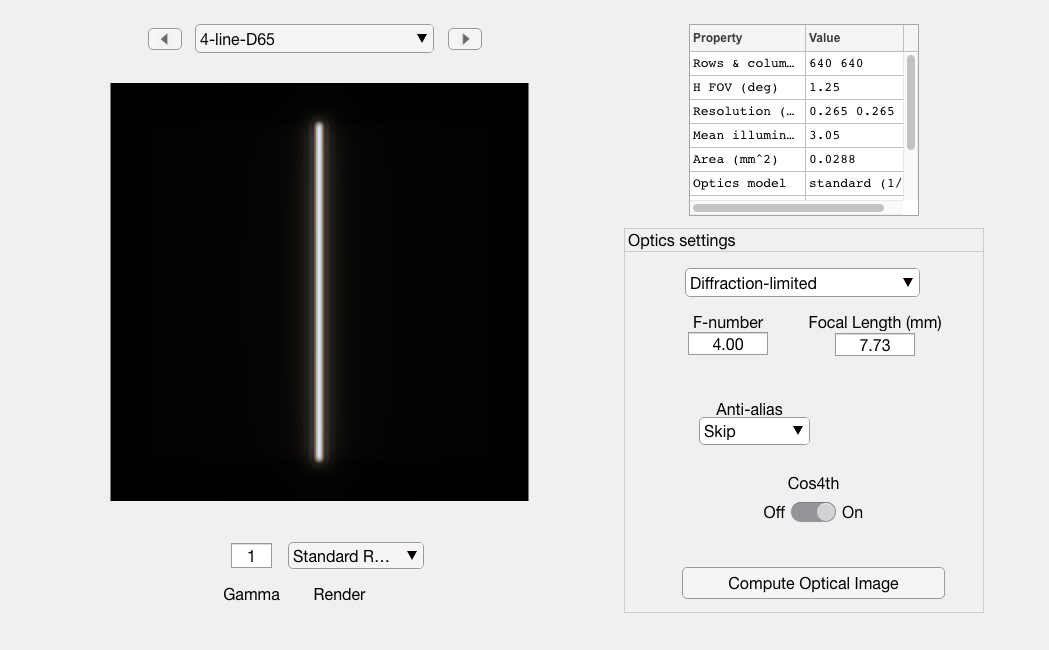

oi2 = oiSet(oi,'optics focal length',oiGet(oi,'optics focal length')*2);
oi2 = oiCompute(oi2,scene);
oiWindow(oi2);

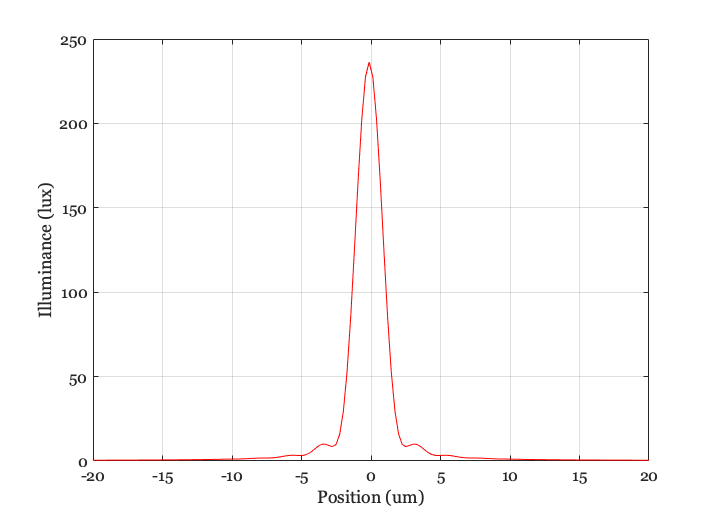


data2 = oiPlot(oi2,'illuminance hline',[1 256]);
set(gca,'xlim',[-20 20],'xtick',[-20:5:20])

Here is an overlay of the two curves, showing that more rays get in from a single thin line.  

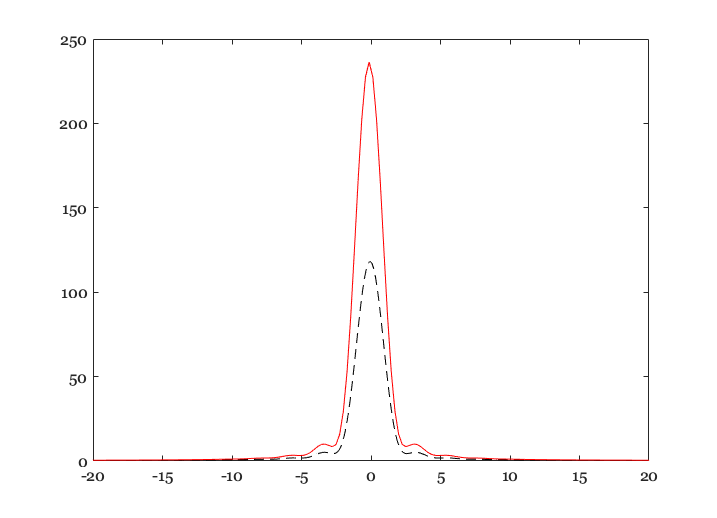

ieNewGraphWin;
plot(data1.pos,data1.data,'k--',data2.pos,data2.data,'r-');
set(gca,'xlim',[-20 20],'xtick',[-20:5:20])

### The magnification

With a grid, you can see the magnification of the images

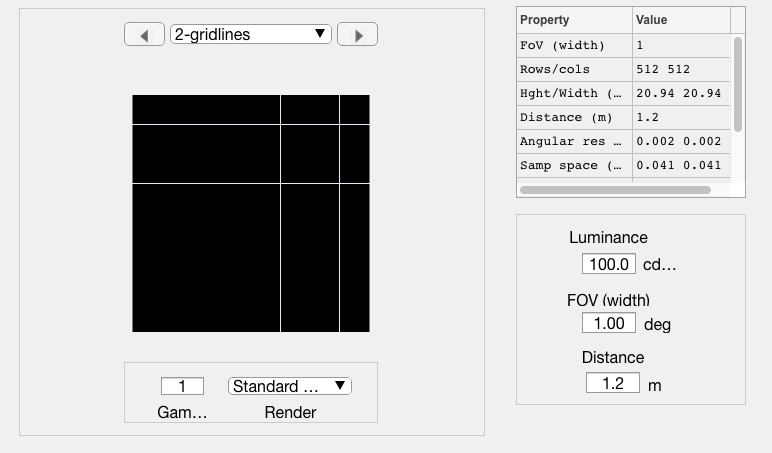

scene = sceneCreate('grid lines',512,128);
scene = sceneSet(scene,'fov',1);
sceneWindow(scene);

The original

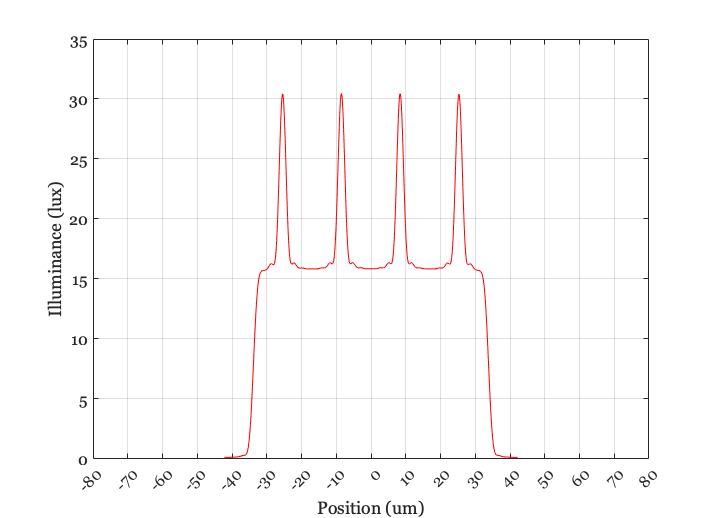

oi = oiCompute(oi,scene);
oiWindow(oi); 
data1 = oiPlot(oi,'illuminance hline',[1 256]);
set(gca,'xlim',[-80 80],'xtick',[-80:10:80]);

The longer focal length

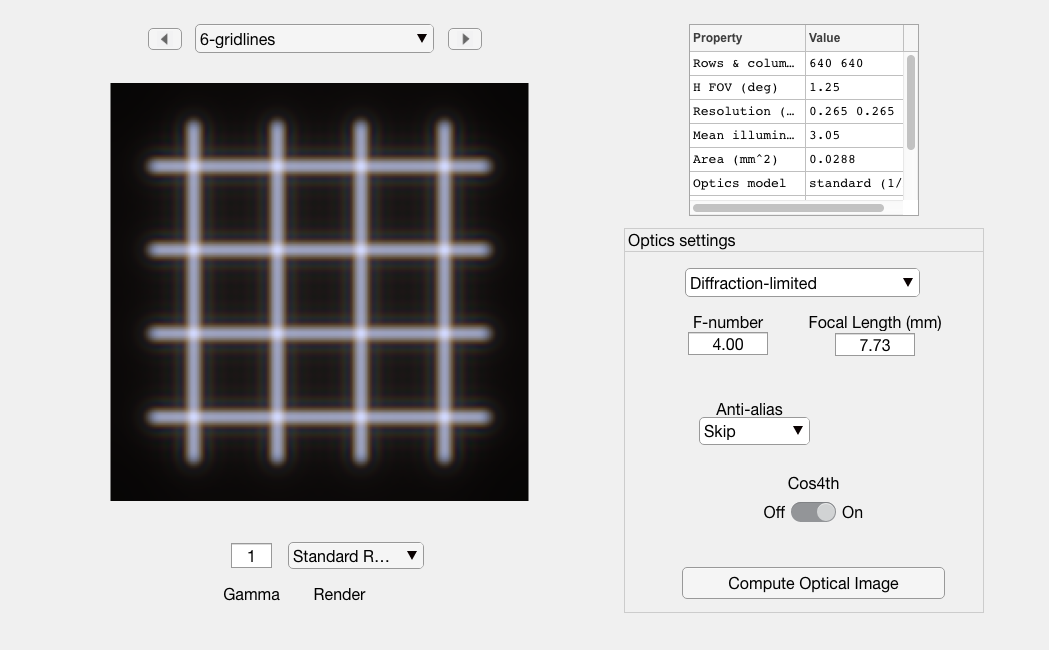

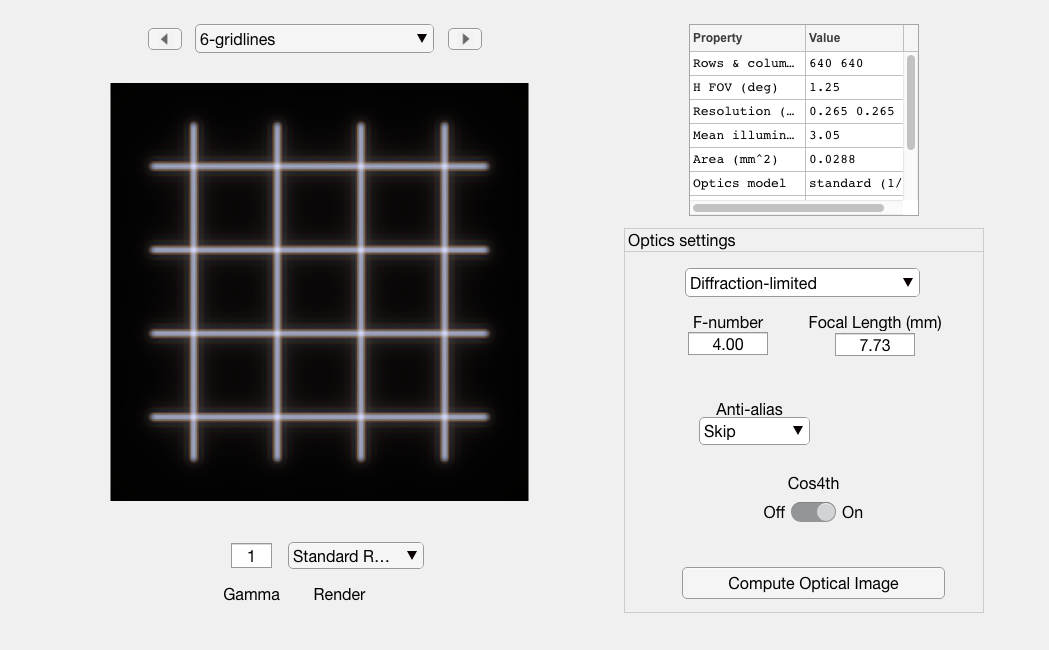

oi2 = oiCompute(oi2,scene);
oiWindow(oi2);

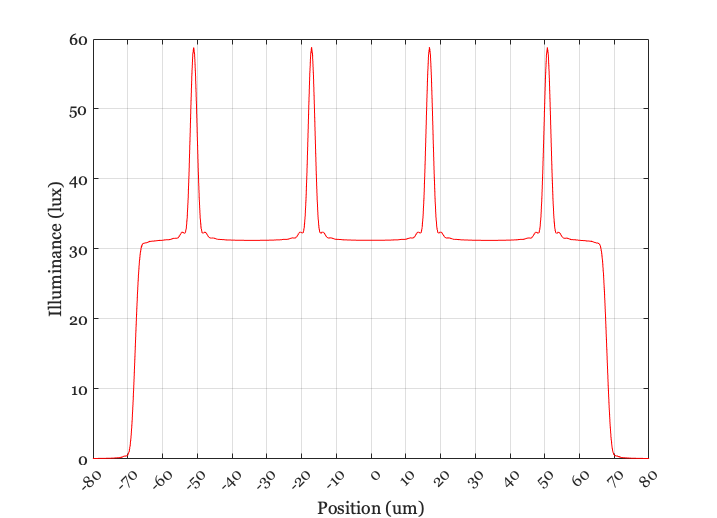

data2 = oiPlot(oi2,'illuminance hline',[1 256]);
set(gca,'xlim',[-80 80],'xtick',[-80:10:80]);

I don't understand this.  Should I be plotting the illuminance corrected for the size of the pixel?  That would bring the two curves into register, right?

The image from the large aperture lens is spread over a wider area.  Summing the area underneath the two curves and then correcting for the total area, brings them together

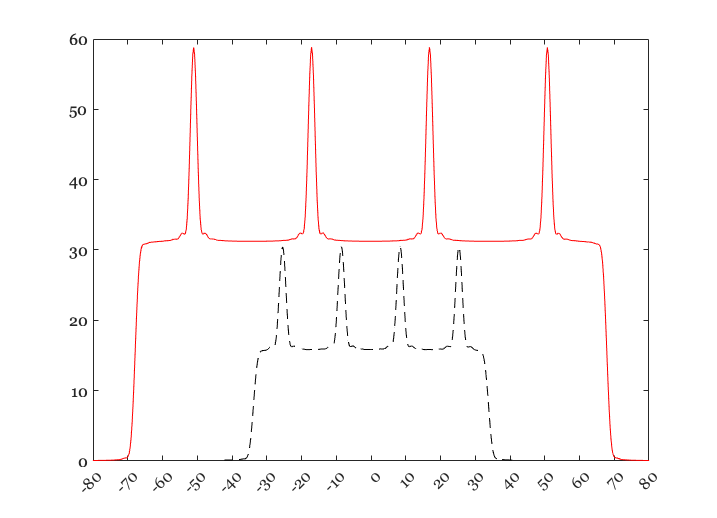

ieNewGraphWin;
plot(data1.pos,data1.data,'k--',data2.pos,data2.data,'r-');
set(gca,'xlim',[-80 80],'xtick',[-80:10:80])


sum(data1.data)/(data1.pos(end) - data1.pos(1))

ans = single
108.8591

sum(data2.data)/(data2.pos(end) - data2.pos(1))

ans = single
100.6561